### Section 4 |

% a)
EEG=load('Assign2_eeg.mat');
[L, tmp] = size(EEG.data);
T = (L-1)/256;
t = 0 : 1/256 : T;
w = 0 : 2*pi / (21.125*256) : 2*pi();
f = 0 : 256/(21.125*256) : 256;

Signal duration is  $\left(5409-1\right)\;/\;256\textrm{Hz}=21\ldotp 125\;\sec \;$

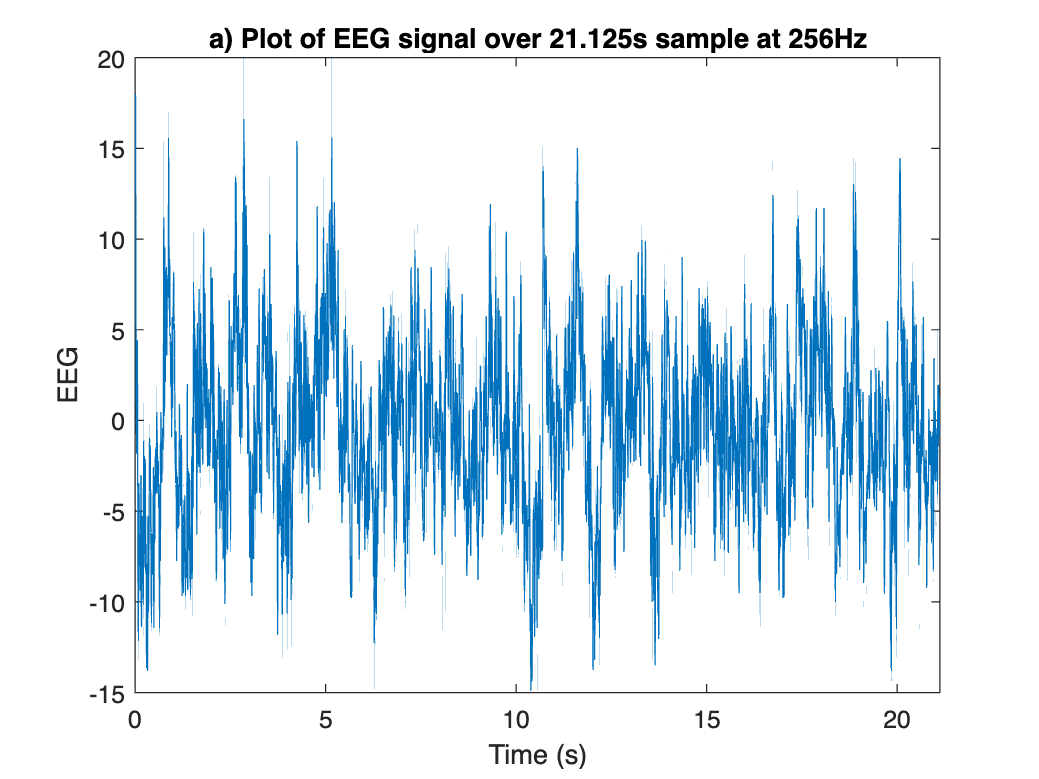

figure1 = figure();
plot(t, EEG.data);
title('a) Plot of EEG signal over 21.125s sample at 256Hz');
xlim([0, T])
xlabel('Time (s)');
ylabel('EEG');

% b)

    The cutoff frequency of the low pass filter can be determined by seeing what frequency components have been suppressed in the FFT representation of the signal. It is clear from the following figure that the FFT is suppressed at frequencies higher than 50Hz, the higher frequencies are really a mirror of the lower frequencies, and they correspond to the lower same DT frequencies as the lower negative frequencies.

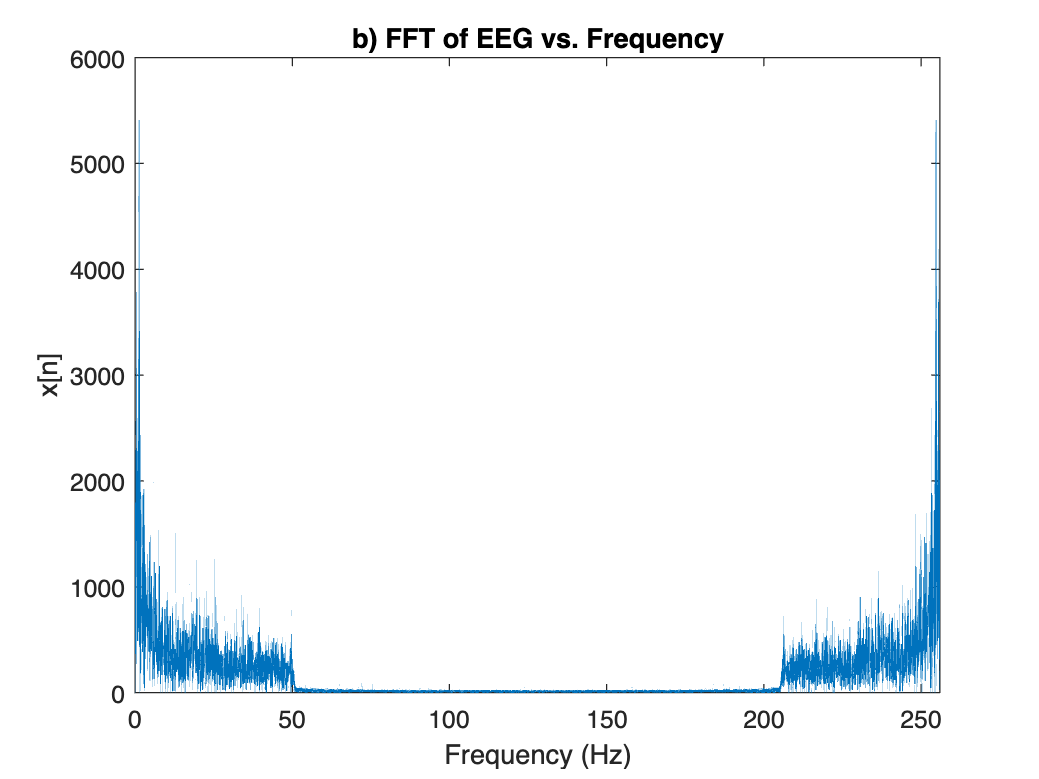


figure2 = figure();
plot(f, abs(fft(EEG.data)));
xlim([0, max(f)])
title('b) FFT of EEG vs. Frequency');
xlabel('Frequency (Hz)');
ylabel('x[n]');


$$\begin{array}{l}
f_c =50\;\textrm{Hz}\\
f_s =256\;\textrm{Hz}=\frac{1}{T_s }\\
T_s =\frac{1}{256}s\\
\Omega {\;}_c =2\pi \;f_c =100\pi \;\\
\omega {\;}_c =\Omega_c T_s \;=100\pi *\frac{1}{256}=1\ldotp 227
\end{array}$$


1.227 is shown in the next graph to shows the cutoff frequency in rads/sample

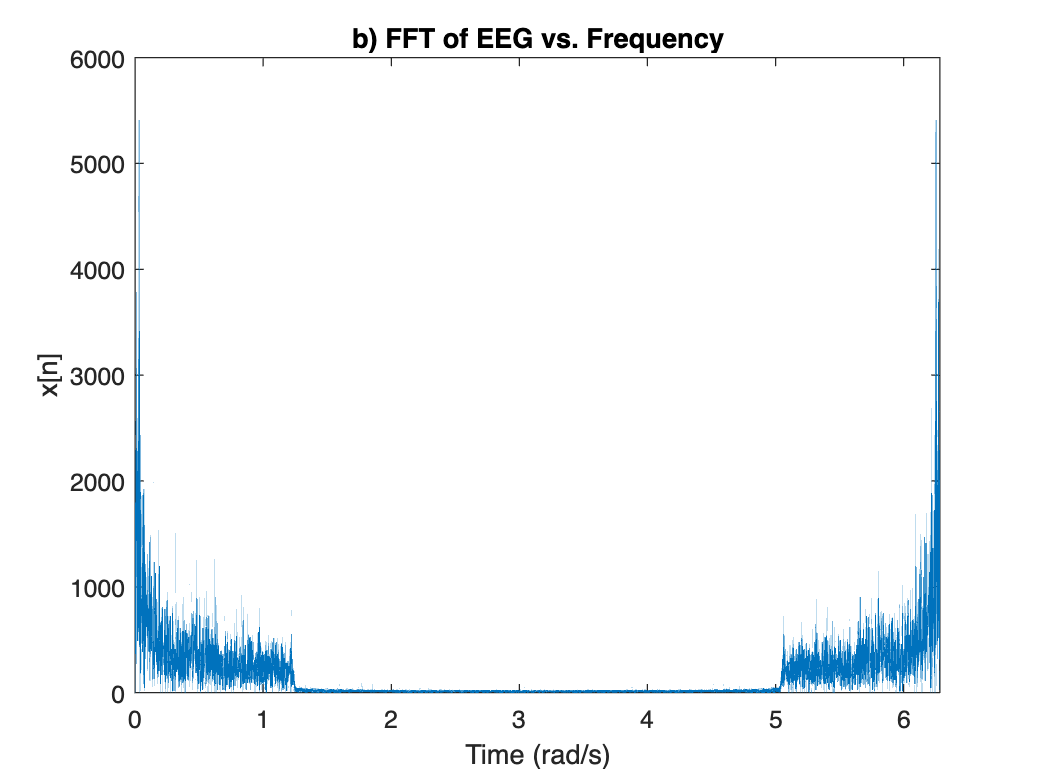

figure3 = figure();
plot(w, abs(fft(EEG.data)));
xlim([0 max(w)])
title('b) FFT of EEG vs. Frequency');
xlabel('Time (rad/s)');
ylabel('x[n]');